%>>>>>>>>>>>>>>>>>>>> Tuterial on AM Modulation <<<<<<<<<<<<<<<<<<<<<<<<<<
clc;
close all;
clear all;
%XXXXXXXXXXXXXXXXXXXXXXXXXXX Define AM modulation Index XXXXXXXXXXXXXXXXXXX
disp(' example: m=1 means 100% modulation');

 example: m=1 means 100% modulation


%m=input(' Enter the value of modulation index (m) = ');
m=0.2; % for 100% modulation
if (0>m||m>1)
error('m may be less than or equal to one and geter than to zero'); 
end

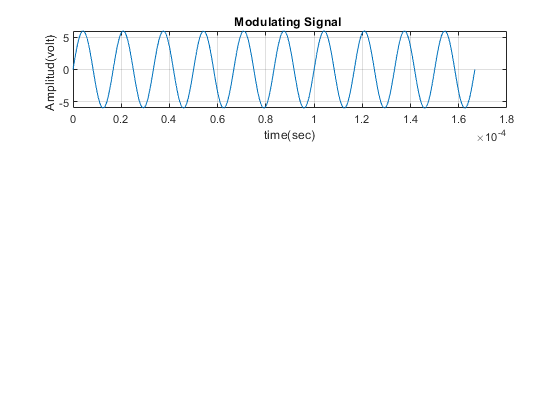

Am=6; % Amplitude of modulating signal
fa=60000; % Frequency of modulating signal
Ta=1/fa; % Time period of modulating signal
t=0:Ta/999:10*Ta; % Total time for simulation
ym=Am*sin(2*pi*fa*t); % Eqation of modulating signal
figure(1)
subplot(3,1,1); 
plot(t,ym), grid on;% Graphical representation of Modulating signal
title ( '  Modulating Signal   ');
xlabel ( ' time(sec) ');
ylabel (' Amplitud(volt)   ');

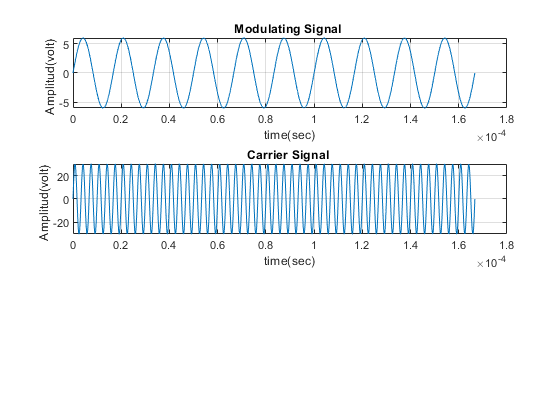

Ac=Am/m;% Amplitude of carrier signal [ where, modulation Index (m)=Am/Ac ]
fc=300000;% Frequency of carrier signal
Tc=1/fc;% Time period of carrier signal
yc=Ac*sin(2*pi*fc*t);% Eqation of carrier signal
subplot(3,1,2);
plot(t,yc), grid on;% Graphical representation of carrier signal
title ( '  Carrier Signal   ');
xlabel ( ' time(sec) ');
ylabel (' Amplitud(volt)   ');

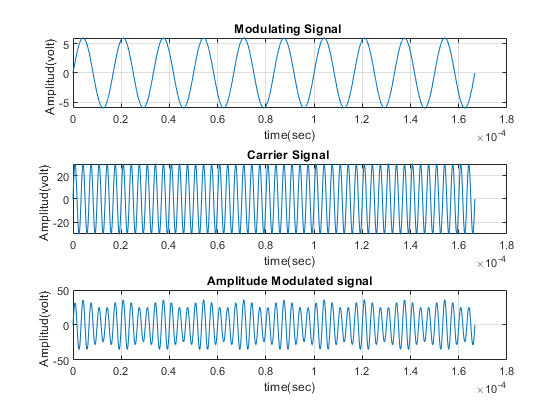

y=Ac*(1+m*sin(2*pi*fa*t)).*sin(2*pi*fc*t); % Equation of Amplitude
%modulated signal
subplot(3,1,3);
plot(t,y);% Graphical representation of AM signal
title ( '  Amplitude Modulated signal  ');
xlabel ( ' time(sec) ');
ylabel (' Amplitud(volt)   ');
grid on;